# Experiment 2.2 MODIFIED

## Name: Test Test

## Objectives

To learn to use MATLAB and the Symbolic Math Toolbox to

- Find Laplace transforms for time functions

- Find time functions from Laplace transforms

- Create LTI transfer functions from symbolic transfer functions.

- Perform solutions of symbolic simultaneous equations.

### Minimum Required Software Packages

MATLAB, the Symbolic Math Toolbox, and the Control System Toolbox.

## Prelab

### Problem 1

*Using a hand calculation, find the Laplace transform of: *$f(t) = 0.0075 - 0.00034 e^{-2.5t}\cos(22t) + 0.087 e^{-2.5t}\sin(22t) - 0.0072 e^{-8t}$

Answer:

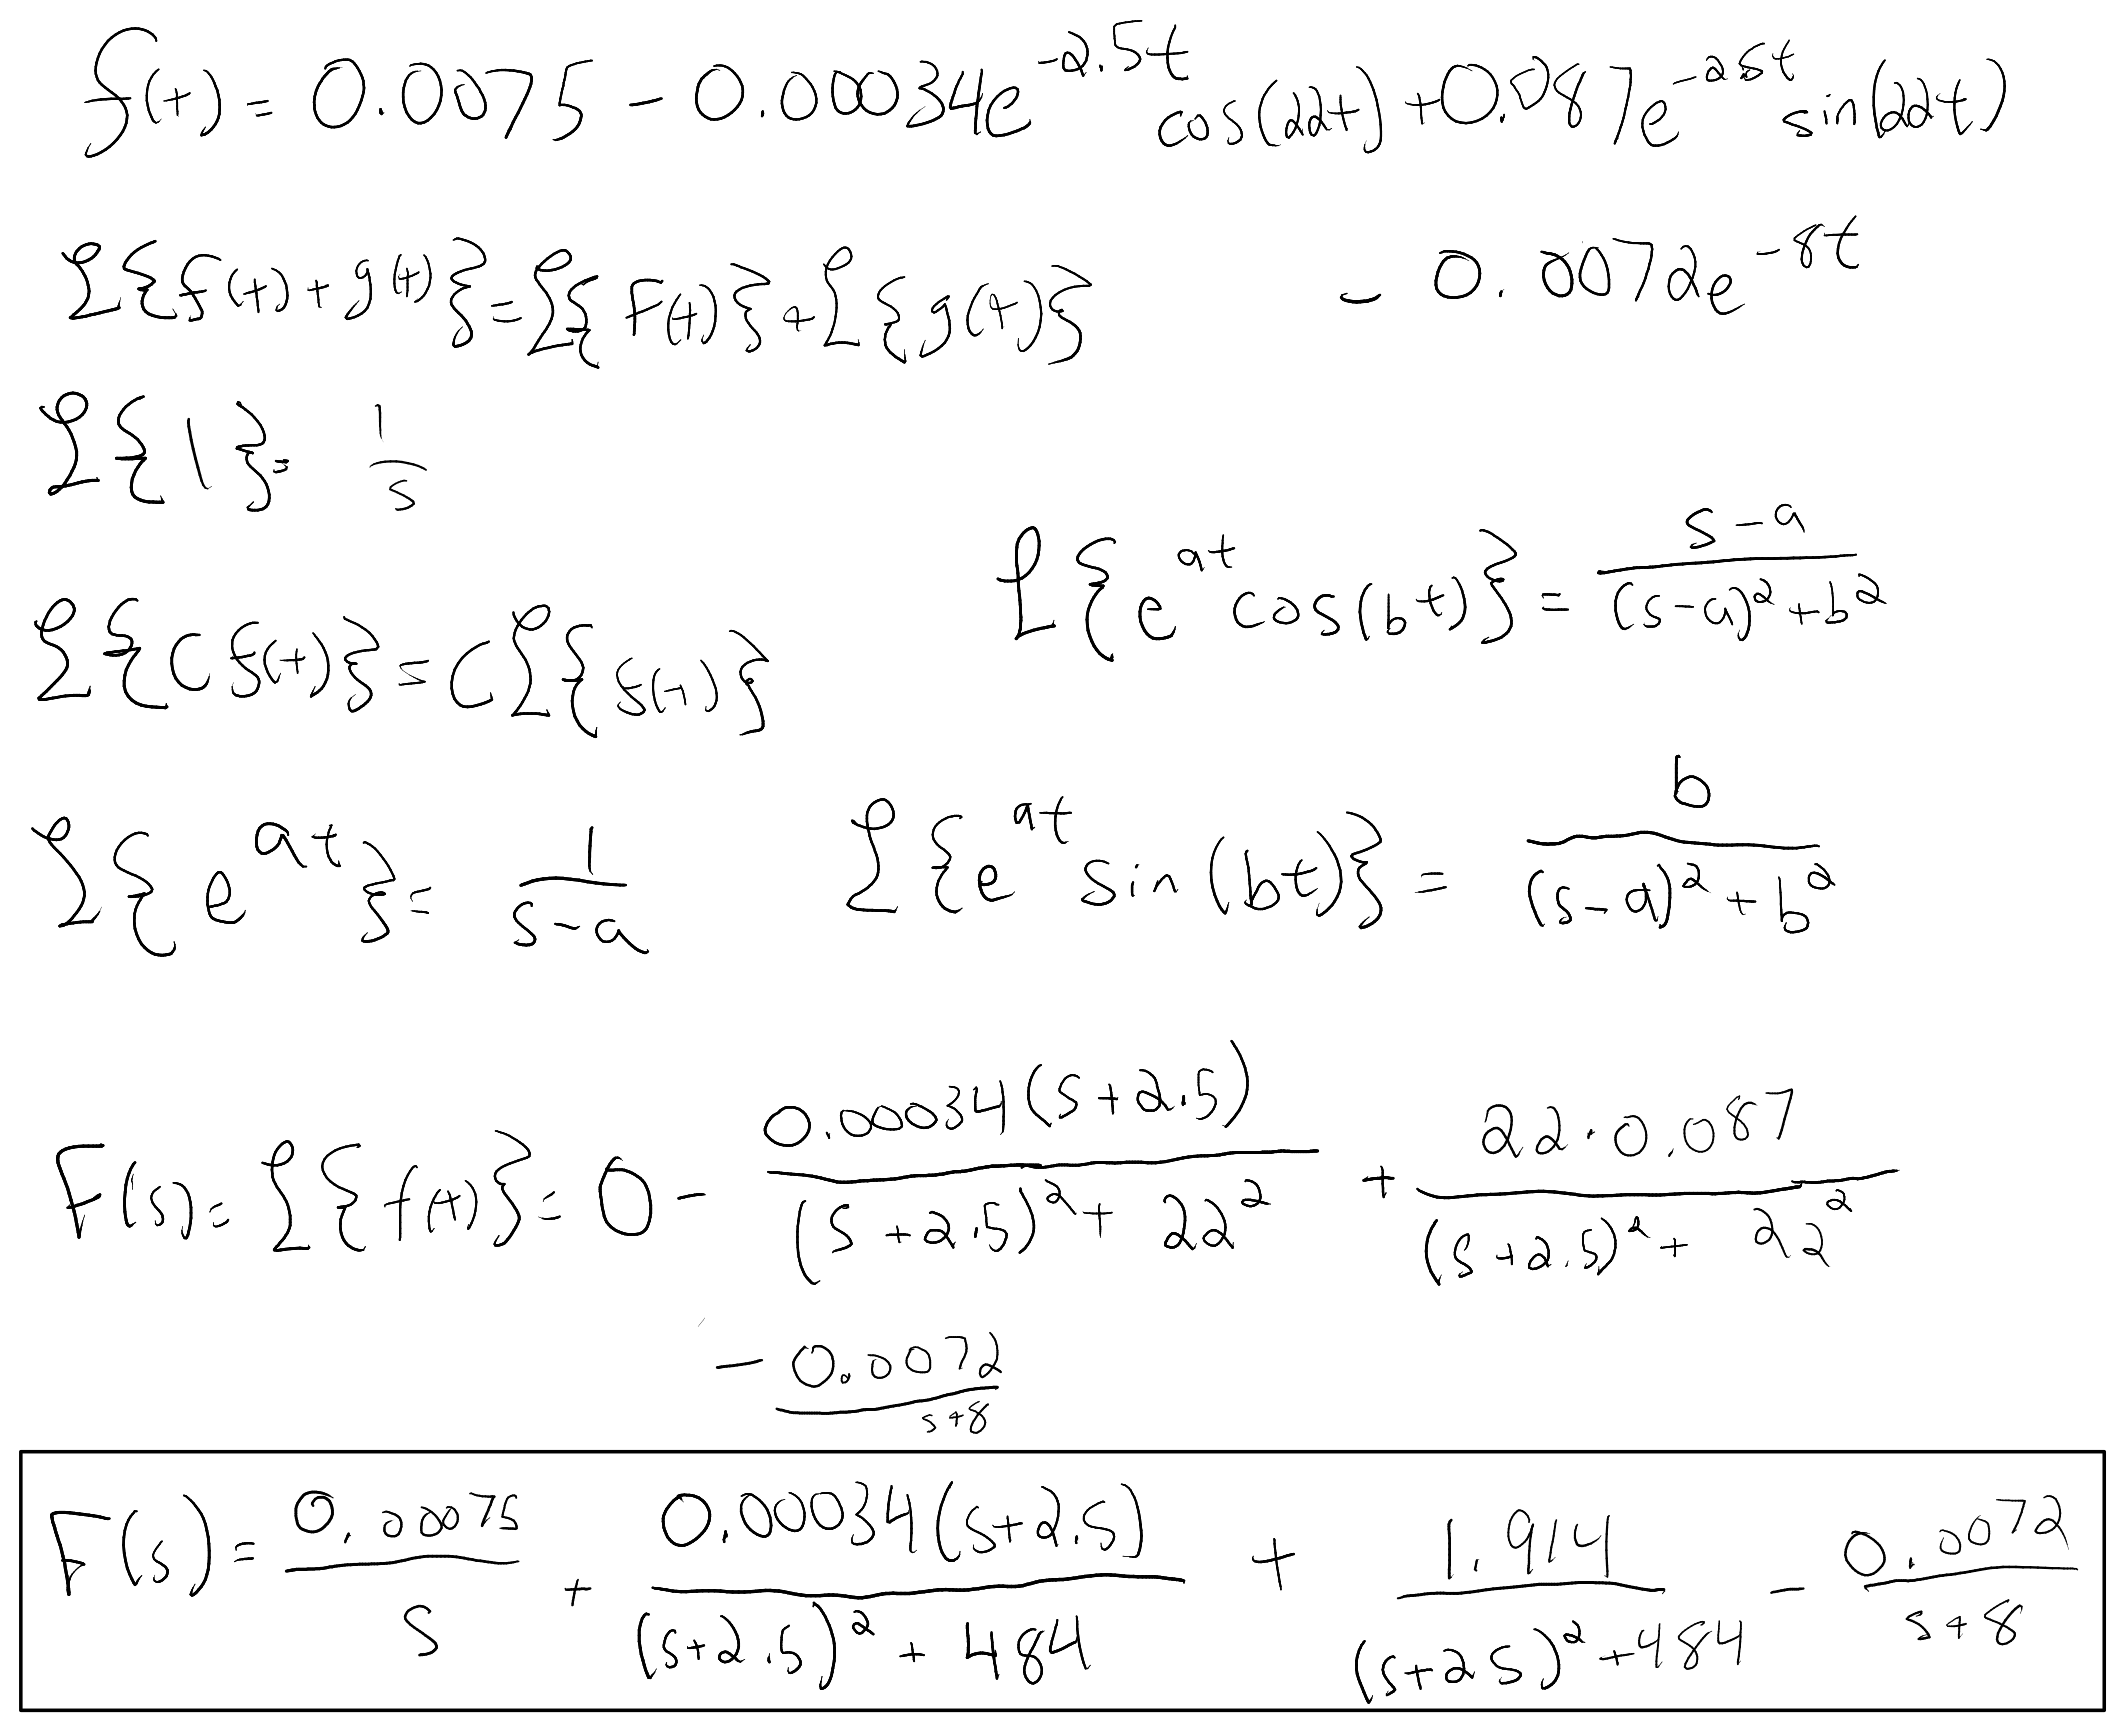

### Problem 2

*Using a hand calculation, find the inverse Laplace transform of: *$F(s) = \frac{2(s+3)(s+5)(s+7)}{s(s+8)(s^2 + 10s + 100)}$

Answer:

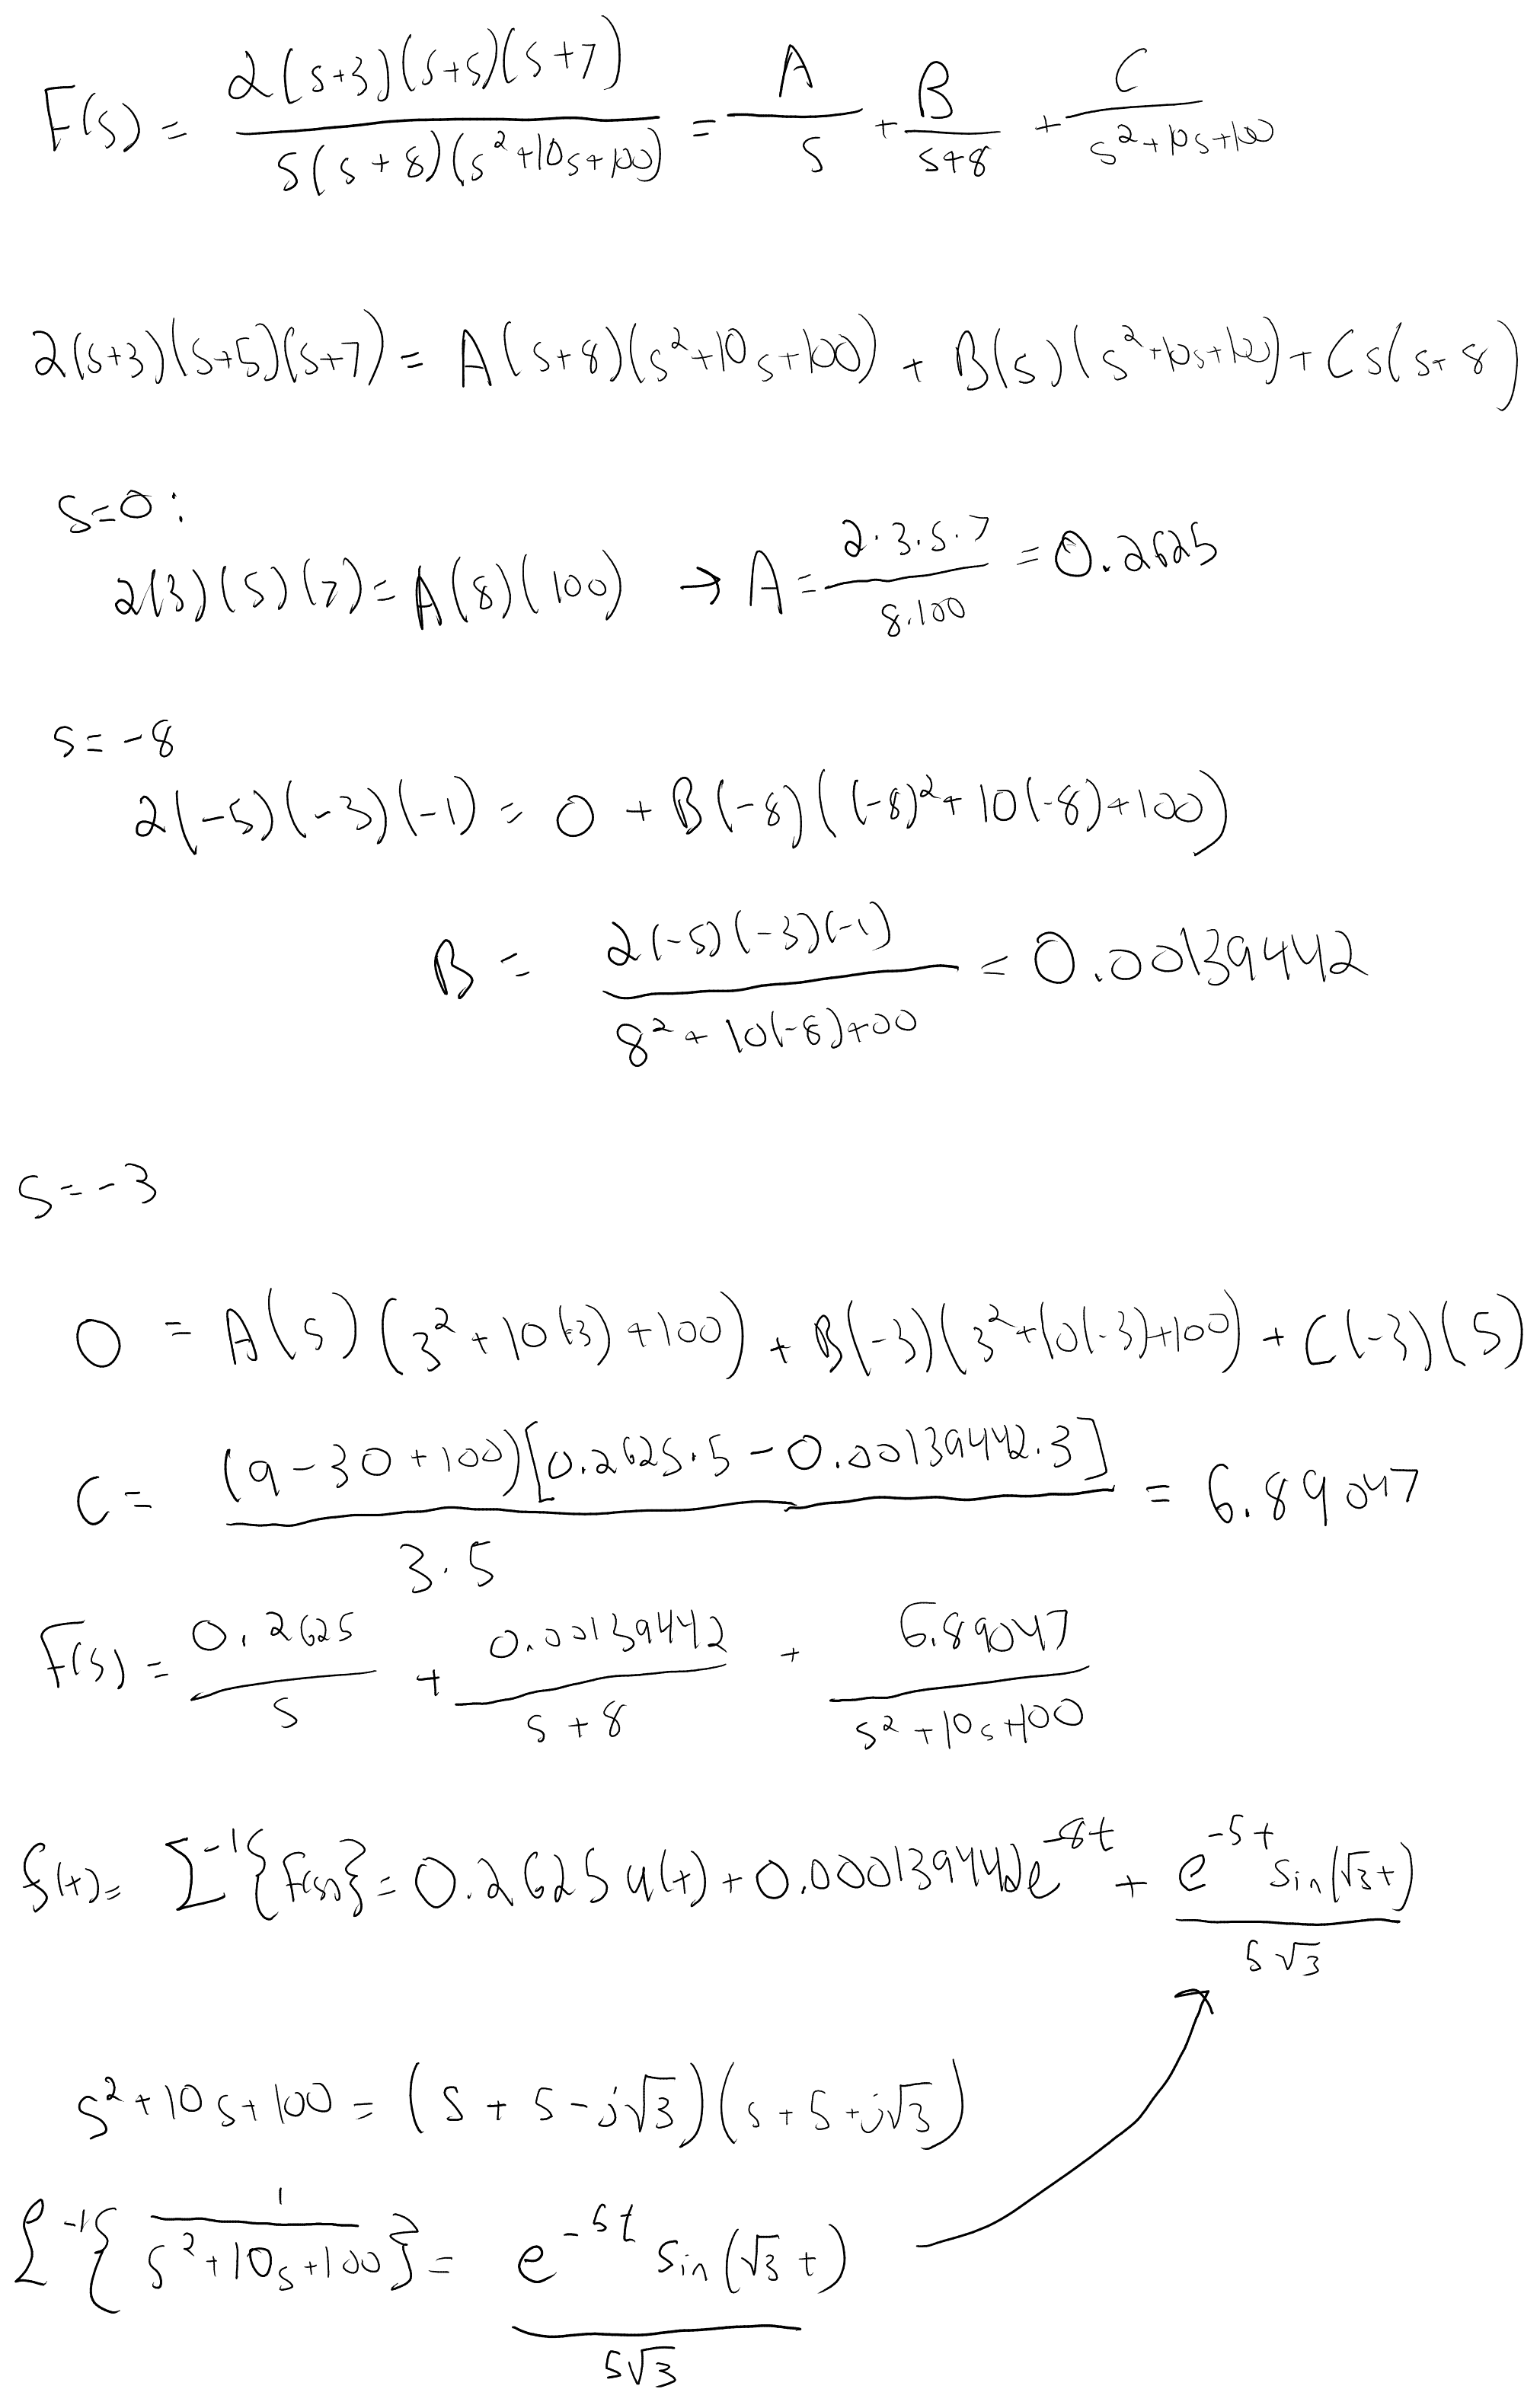

### Problem 3

*Calculate by hand the transfer function of the following systems. Then solve for the rise time, poles, and the steady-state final value for the step-response.*

#### *3.a.*

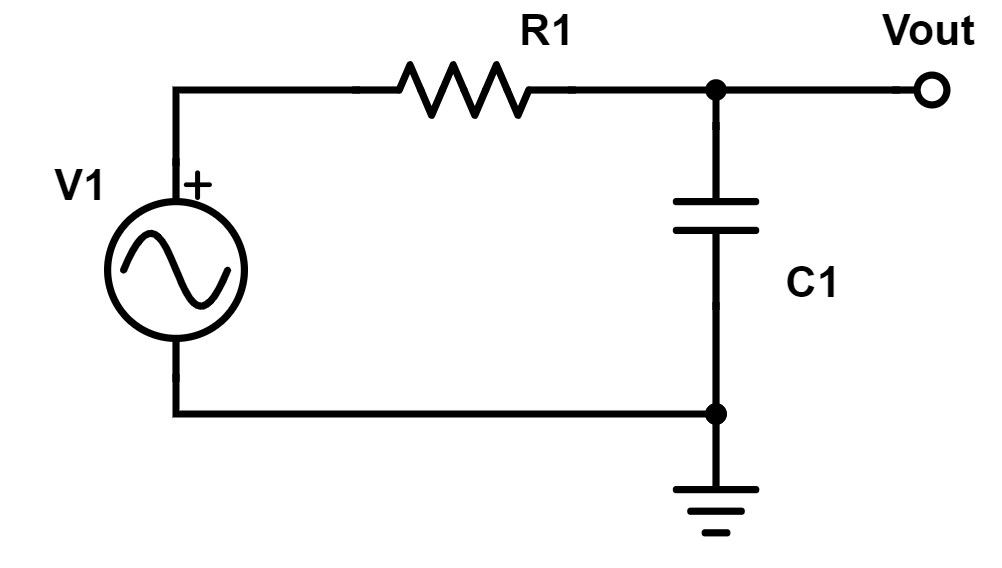

Answer:

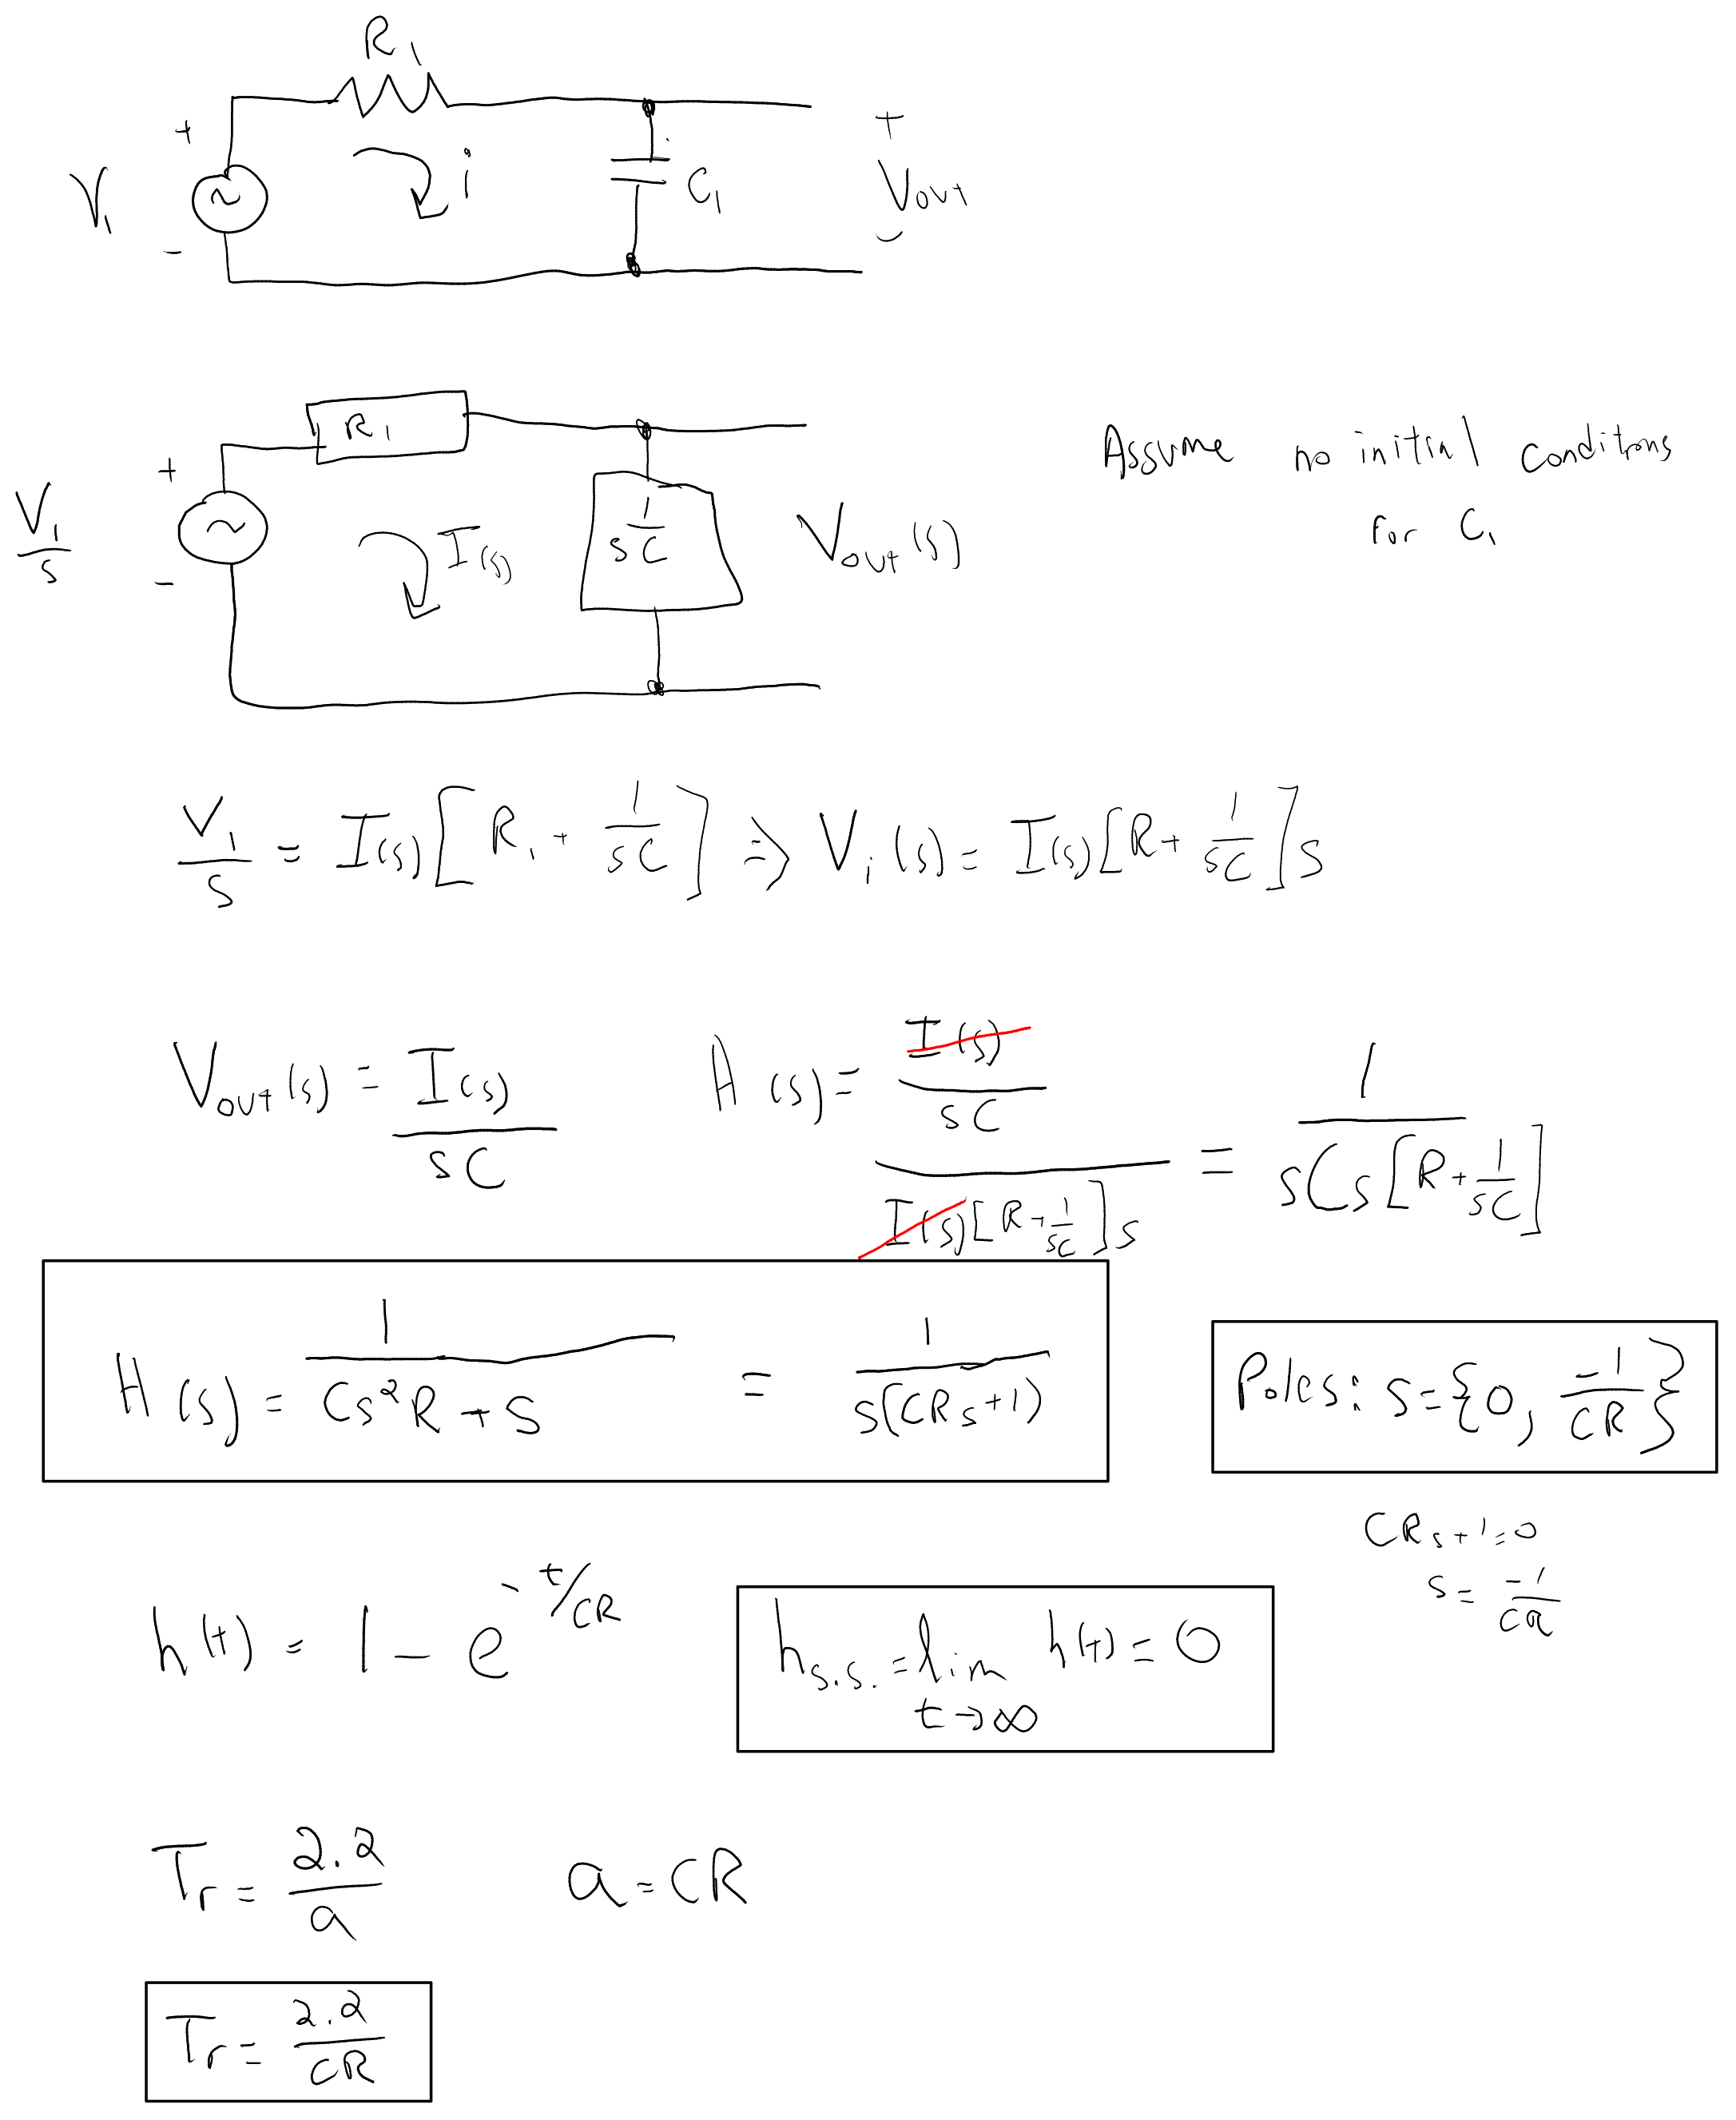

#### 3.b.

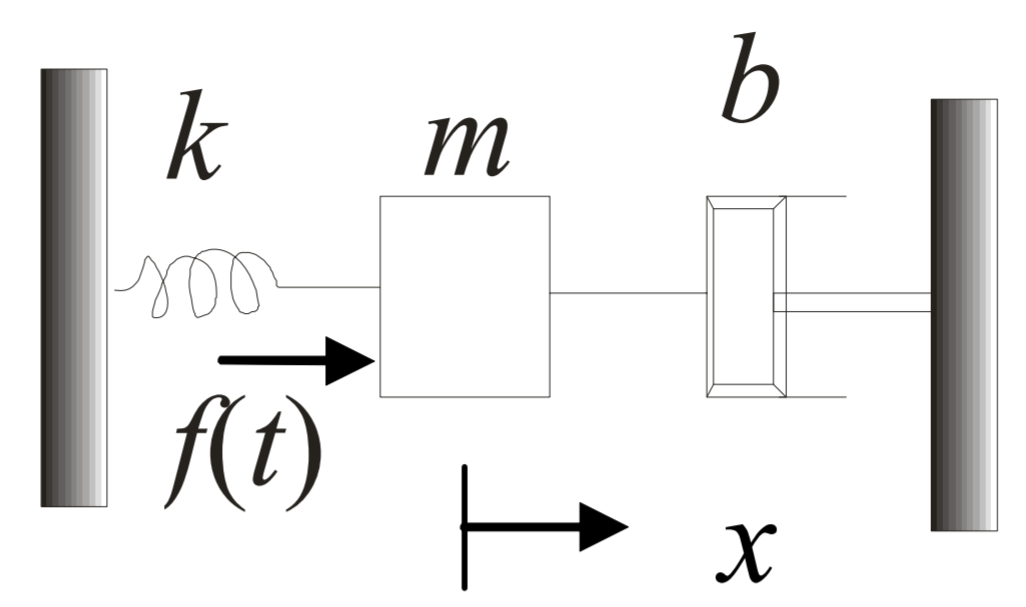

For this problem, **ONLY SOLVE FOR THE TRANSFER FUNCTION.** You will be looking for the displacement caused by the force.

Answer:

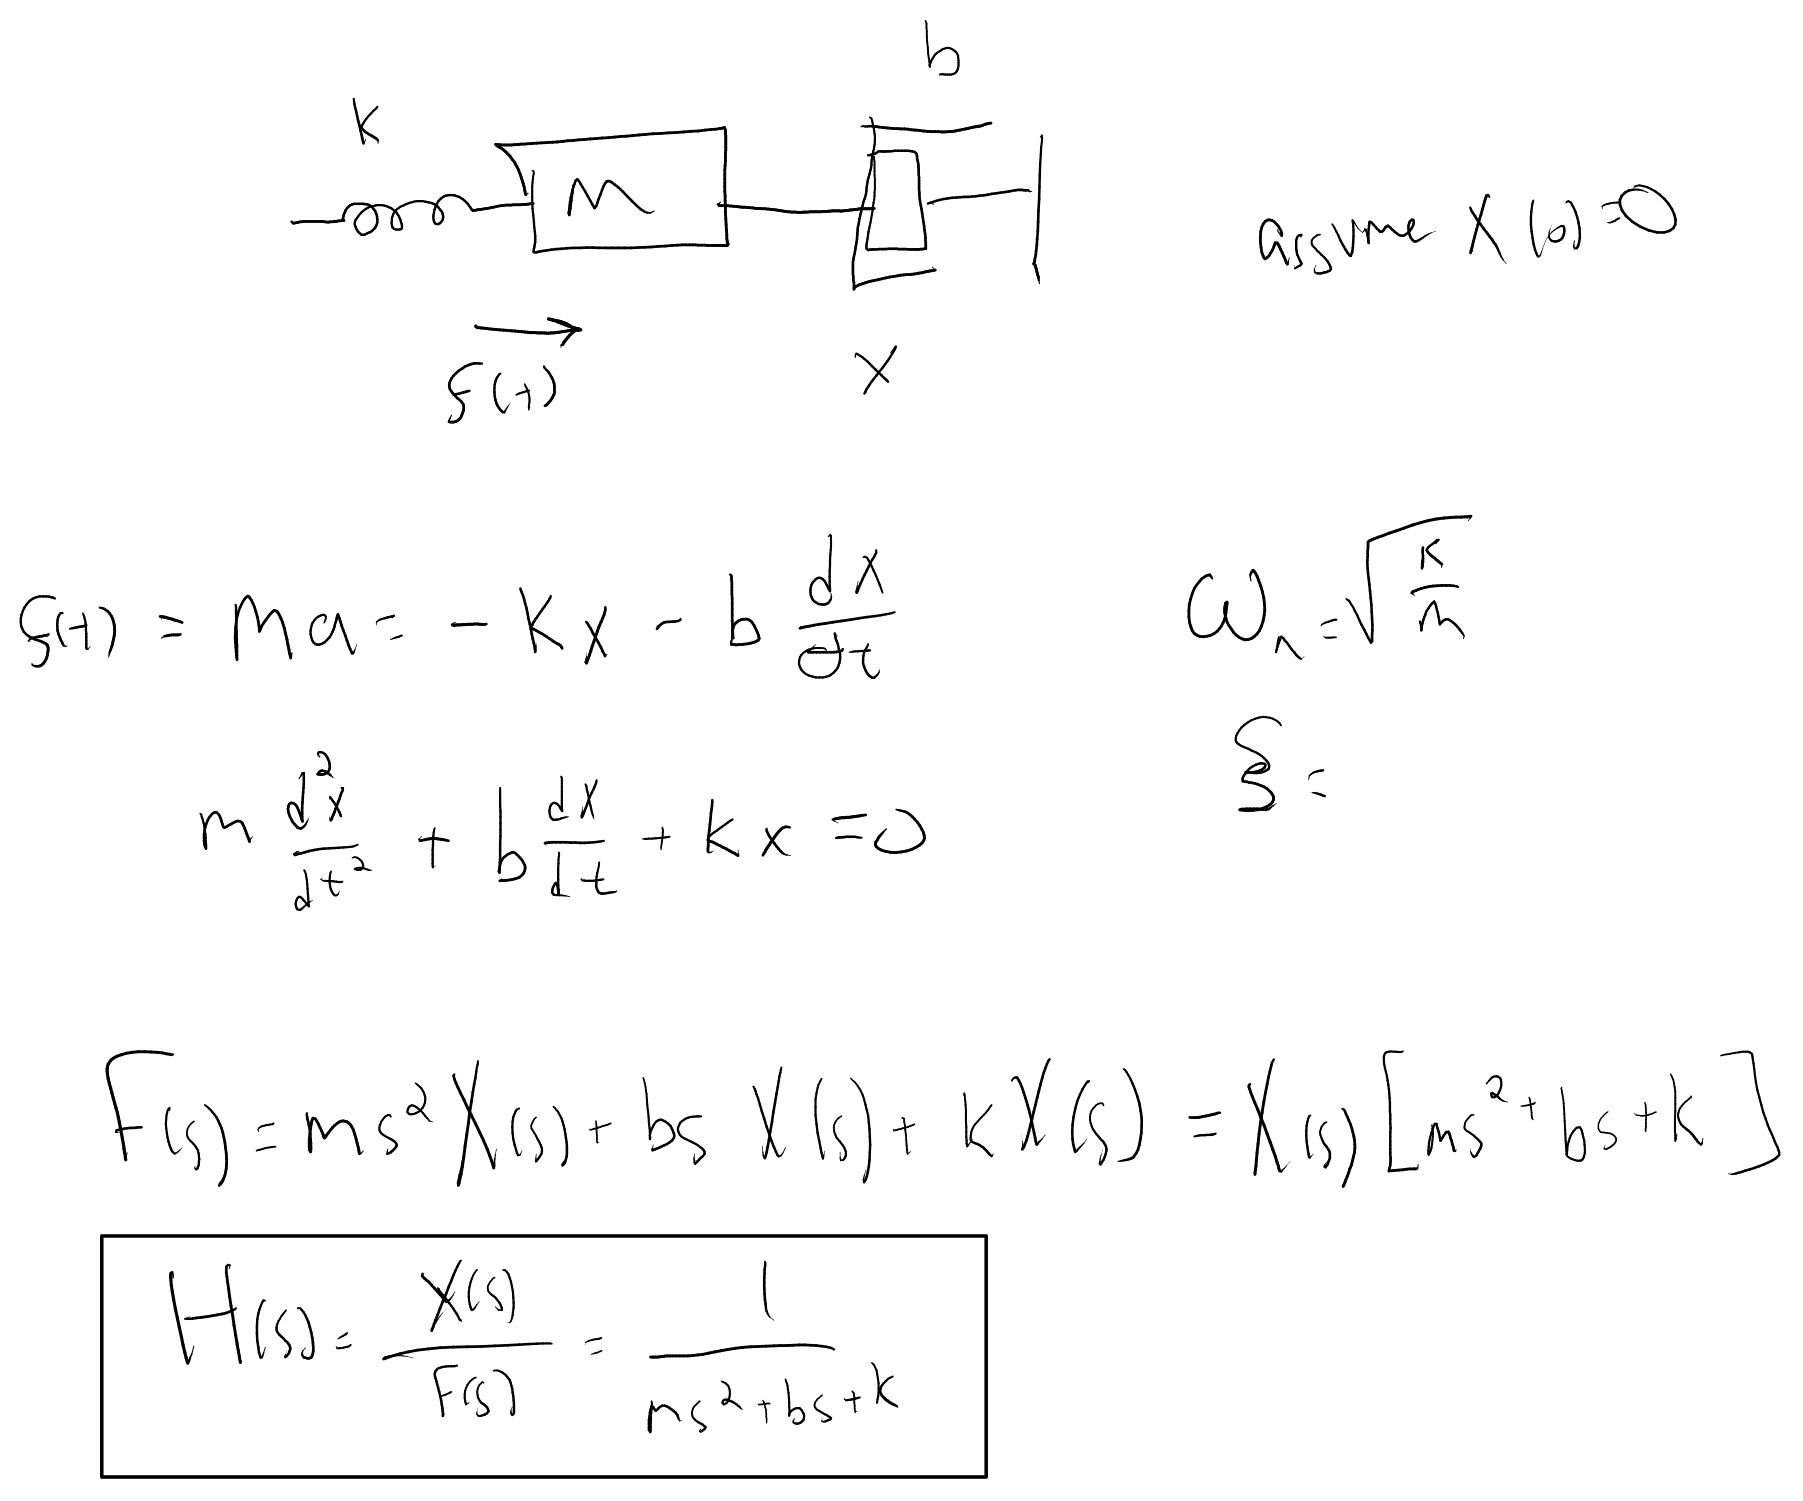

#### 3.c.

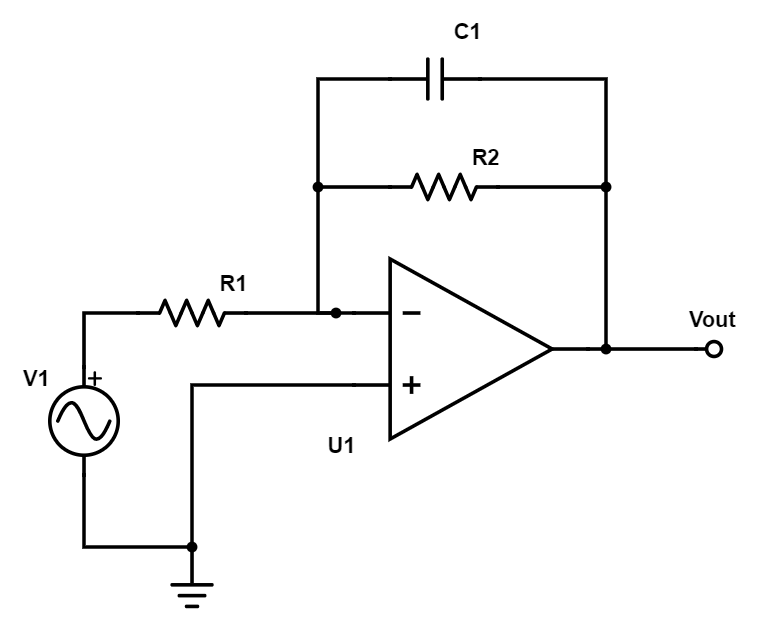

Answer:

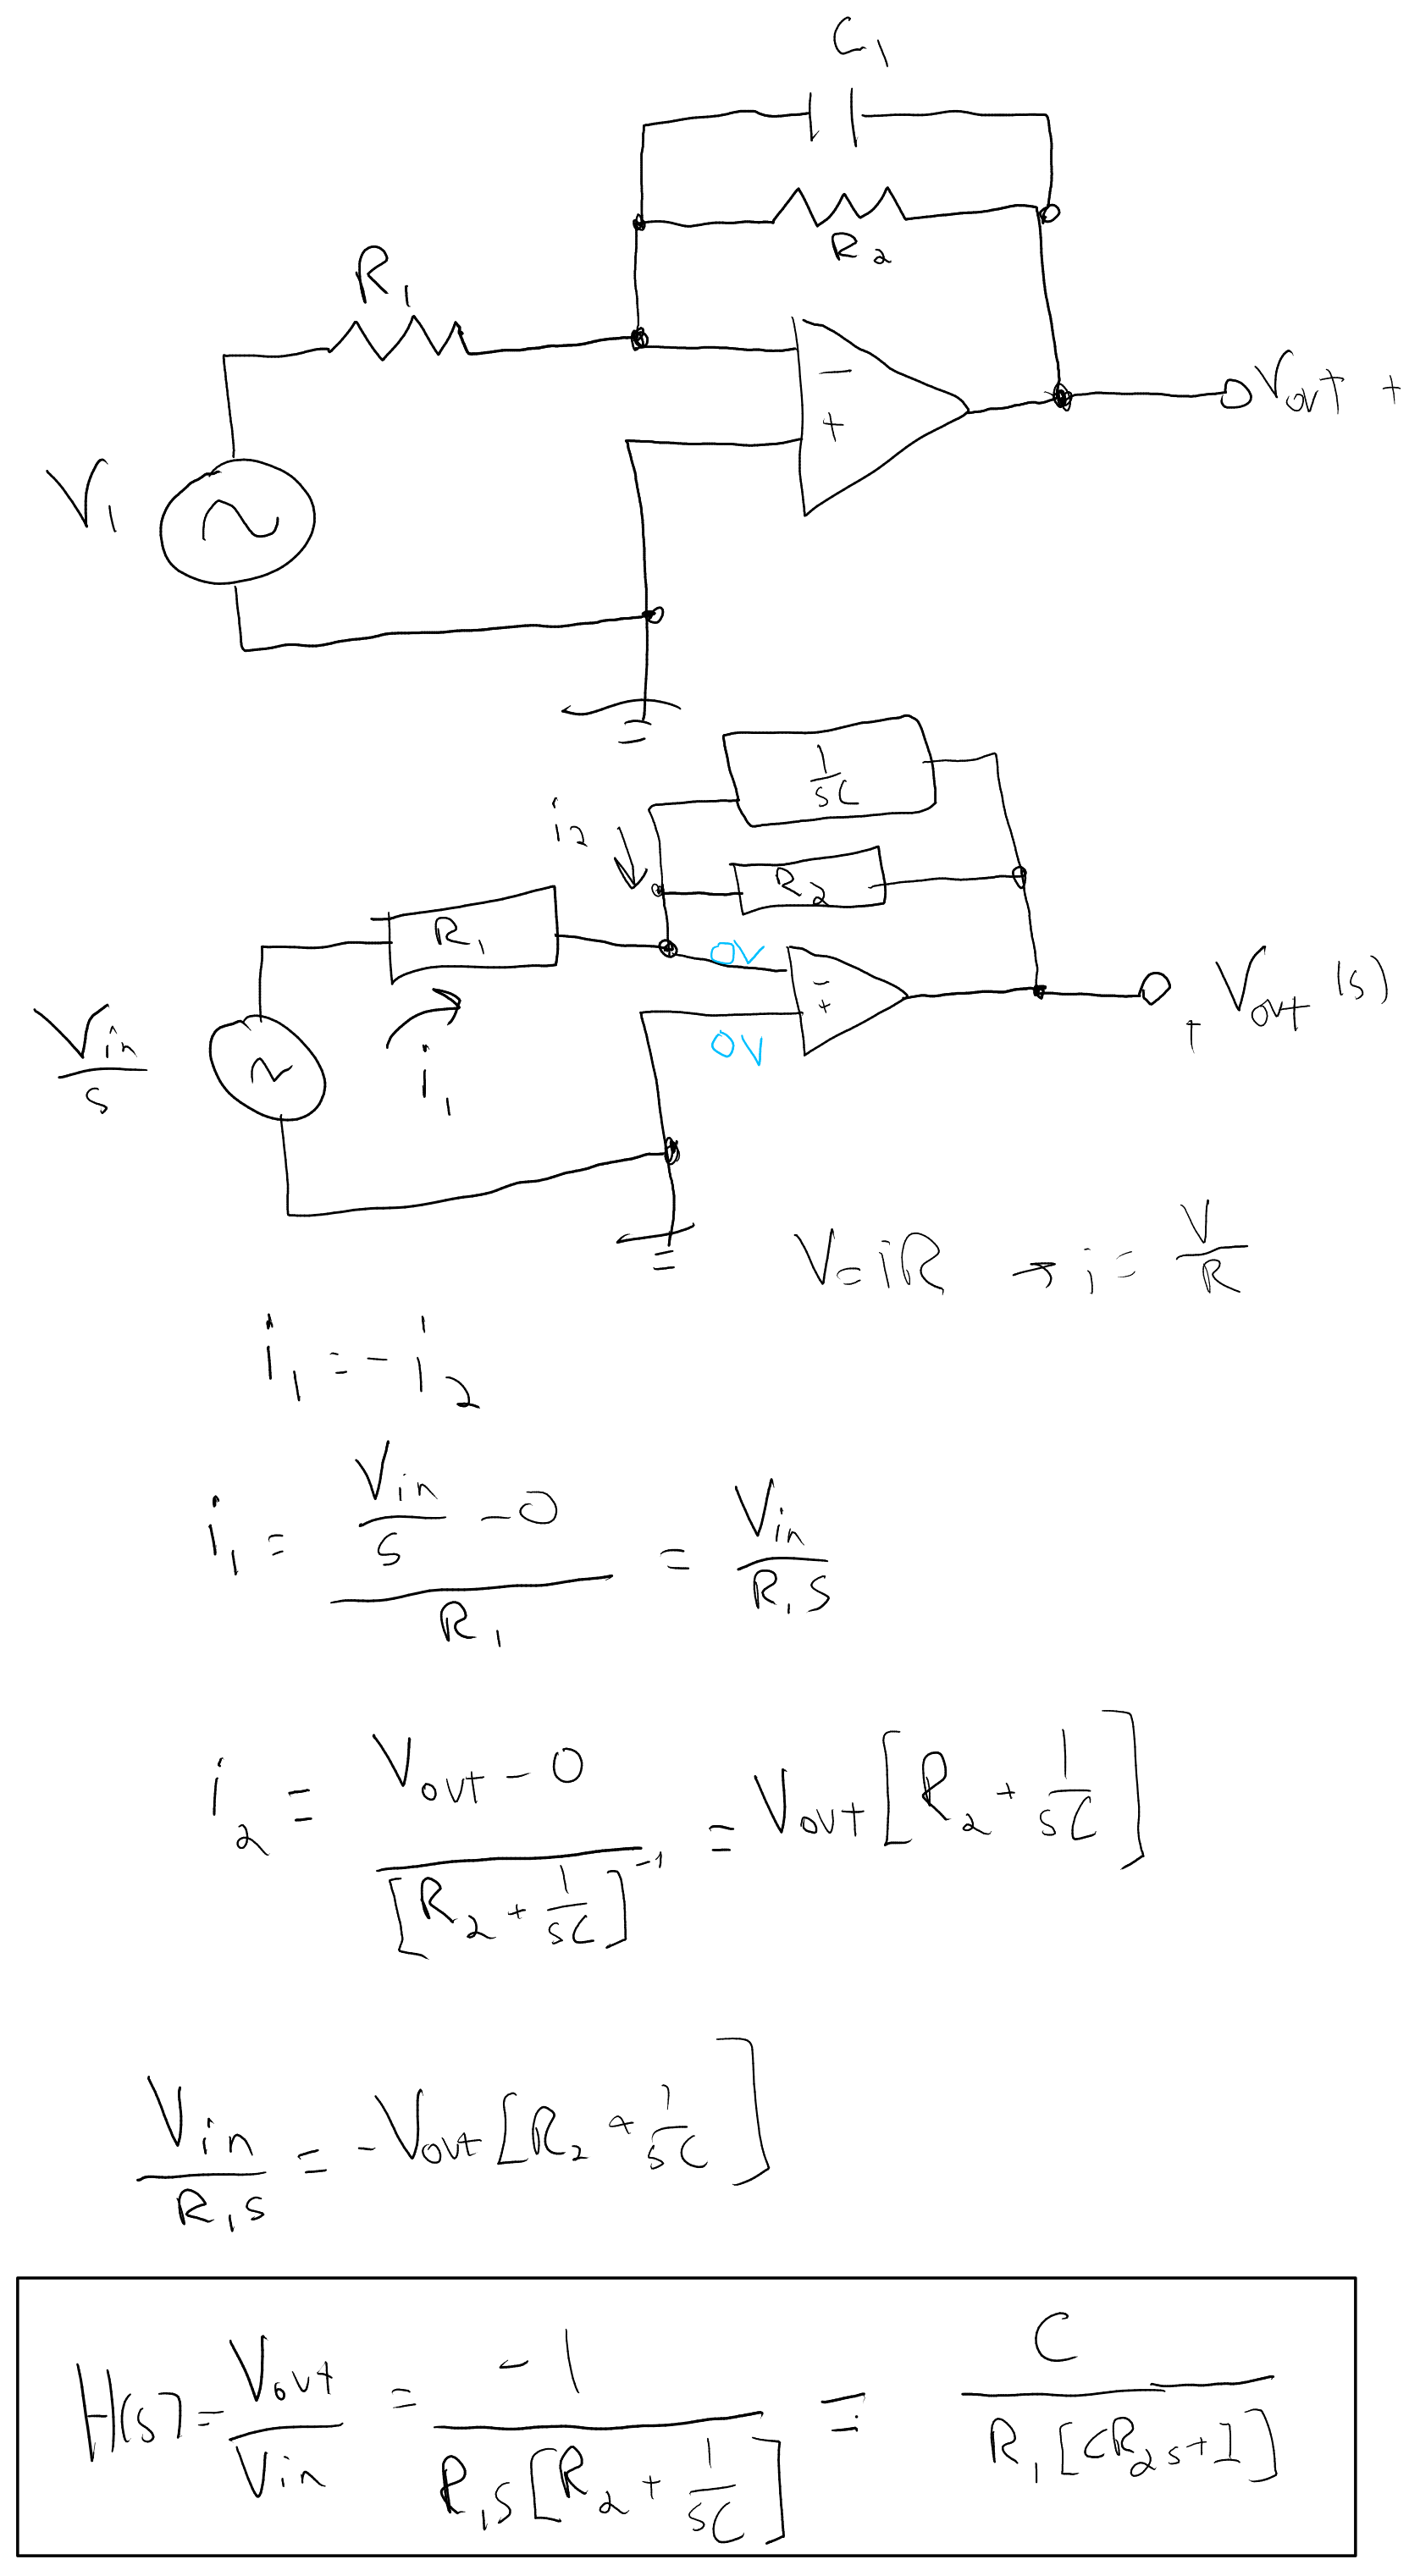

## Lab

### Problem 1

*Use MATLAB and the Symbolic Math Toolbox to*

#### 1.a.

*Generate symbolically the time function f(t) shown in Prelab Problem 1*

syms t;
syms s;
f(t) = 0.0075-0.00034*exp(-2.5*t)*cos(22*t)+0.087*exp(-2.5*t)*sin(22*t)-0.0072*exp(-8*t);
vpa(f(t))

$$ans = 0.087\,{\mathrm{e}}^{-2.5\,t}\,\sin\left(22.0\,t\right)-0.00034\,{\mathrm{e}}^{-2.5\,t}\,\cos\left(22.0\,t\right)-0.0072\,{\mathrm{e}}^{-8.0\,t}+0.0075$$

#### 1.b.

*Generate symbolically F(s) shown in Prelab Problem 2. Obtain your result symbolically in both factored and polynomial form*

F(s)=laplace(f(t));
vpa(F(s))

$$ans = \frac{1.914}{{\left(s+2.5\right)}^{2}+484.0}-\frac{0.0072}{s+8.0}-\frac{0.00034\,\left(s+2.5\right)}{{\left(s+2.5\right)}^{2}+484.0}+\frac{0.0075}{s}$$

factor(F(s),s)

$$ans = \left(\begin{array}{ccccc} -\frac{1}{50000} & 8\,s^{3}-394386\,s^{2}-3150455\,s-5883000 & \frac{1}{s} & \frac{1}{s+8} & \frac{1}{4\,s^{2}+20\,s+1961} \end{array}\right)$$

#### 1.c.

*Find the Laplace Transform of f(t) shown in Prelab Problem 1*

vpa(laplace(f(t)))

$$ans = \frac{1.914}{{\left(s+2.5\right)}^{2}+484.0}-\frac{0.0072}{s+8.0}-\frac{0.00034\,\left(s+2.5\right)}{{\left(s+2.5\right)}^{2}+484.0}+\frac{0.0075}{s}$$

#### 1.d.

*Find the inverse Laplace Transform of F(s) shown in Prelab Problem 2*

vpa(expand(vpa(ilaplace(F(s)),3)),3)

$$ans = 0.087\,{\mathrm{e}}^{-2.5\,t}\,\sin\left(22.0\,t\right)-3.4\,10^{-4}\,{\mathrm{e}}^{-2.5\,t}\,\cos\left(22.0\,t\right)-0.0072\,{\mathrm{e}}^{-8.0\,t}+0.0075$$

### Problem 2

*Using MATLAB, find the values for the characteristics requested in Prelab Problem 3.a. given *$R_1 = 1k\Omega, C_1 = 1\mu F$. *Using only MATLAB (no Simulink) find and plot the step response of the system.*

R1=1e3;
C1=1e-6;

H(s)= 1/(C1*R1*s+1)

$$H(s) = \frac{1}{\frac{s}{1000}+1}$$

[symNum,symDen] = numden(H(s)); %Get num and den of Symbolic TF
TFnum = sym2poly(symNum);    %Convert Symbolic num to polynomial
TFden = sym2poly(symDen);
sys = tf(TFnum,TFden)


sys =
 
    1000
  --------
  s + 1000
 
Continuous-time transfer function.



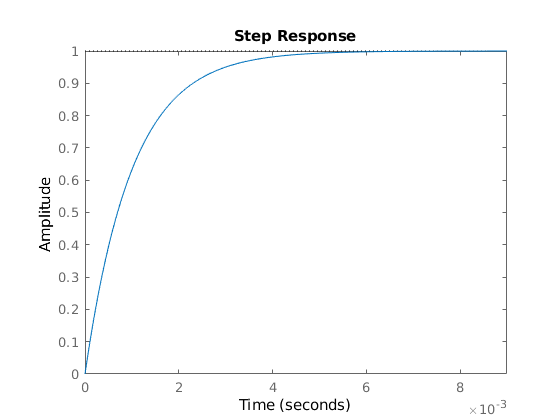

step(sys)


stepinfo(sys);
Poles=poles(H(s))

$$Poles = -1000$$

RiseTime = S.RiseTime

RiseTime = 0.0022

SteadyState = S.SettlingMax

SteadyState = 1.0000

### Problem 4

#### 4.a.

*Using MATLAB, find the charcteristics requested in Prelab Problem 3.b. given *$k=2$ $b=20$, $m=2$. Plot the step response of the system and find the rise time and settling time.

k=2;
b=20;
m=2;
sys = tf([1],[m,b,k])


sys =
 
         1
  ----------------
  2 s^2 + 20 s + 2
 
Continuous-time transfer function.



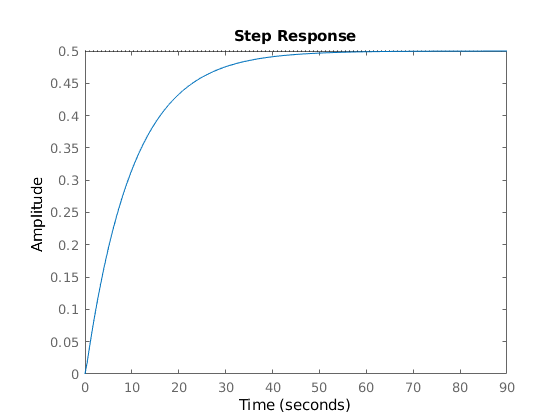

step(sys)

stepinfo(sys)

ans = struct with fields:
        RiseTime: 21.7495
    SettlingTime: 38.8281
     SettlingMin: 0.4518
     SettlingMax: 0.5000
       Overshoot: 0
      Undershoot: 0
            Peak: 0.5000
        PeakTime: 104.3931


#### 4.b.

*Using sliders in the live script, find the value for *$b$ *where it stops acting like a first order system.*

% Insert your code here
m = 2

m = 2

b = 3

b = 3

k = 2

k = 2

G = tf([1], [m, b, k])


G =
 
         1
  ---------------
  2 s^2 + 3 s + 2
 
Continuous-time transfer function.



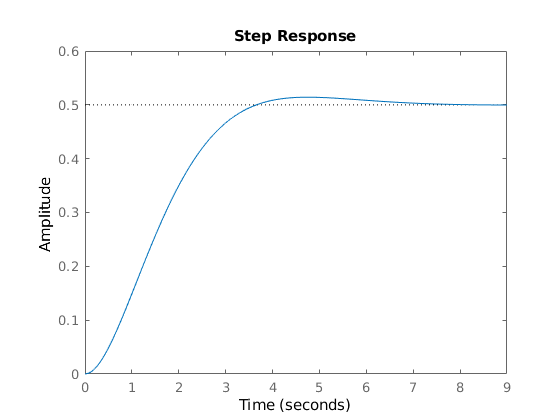

step(G)

pole(G)

ans =   -0.7500 + 0.6614i
  -0.7500 - 0.6614i


[u,v] = step(G);
risetime(u)

ans = 39.0190

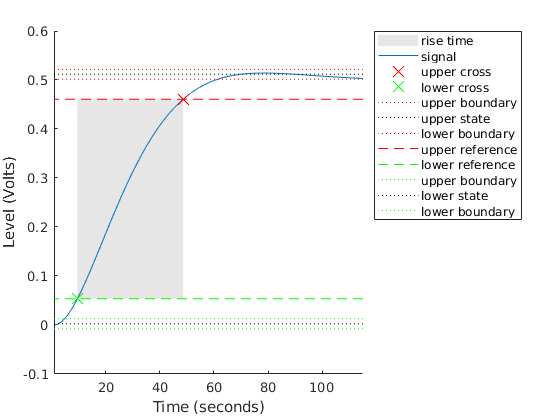


xlim([1 115])

stepinfo(G)

ans = struct with fields:
        RiseTime: 2.2884
    SettlingTime: 5.7426
     SettlingMin: 0.4524
     SettlingMax: 0.5142
       Overshoot: 2.8369
      Undershoot: 0
            Peak: 0.5142
        PeakTime: 4.7280


**At b<=3, the system stops acting like a first order system**

### Problem 5

*For Prelab 3.c. find the rise-time for the circuit with the values of *$R_1 = 1k\Omega , R_2 = 1k\Omega, C_1 = 1\mu F$*. Using sliders and your transfer function from the Prelab, determine what happens to the step response and the rise time as you change *$R_1$ *and *$R_2$.

R1=1000;
R2=1000;
C1=1e-6;

sys=tf([C1],[R1*R2*C1 R1])


sys =
 
   1e-06
  --------
  s + 1000
 
Continuous-time transfer function.



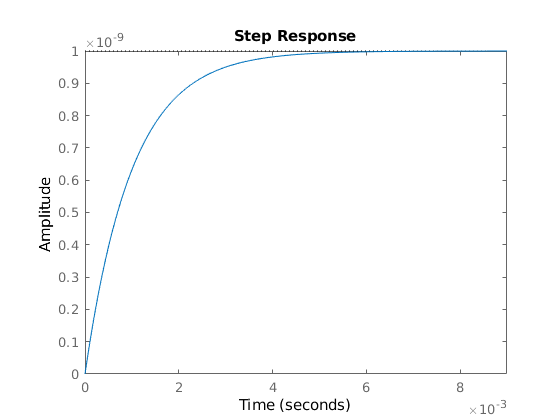

step(sys)

stepinfo(sys)

ans = struct with fields:
        RiseTime: 0.0022
    SettlingTime: 0.0039
     SettlingMin: 9.0000e-10
     SettlingMax: 9.9997e-10
       Overshoot: 0
      Undershoot: 0
            Peak: 9.9997e-10
        PeakTime: 0.0105


**RiseTime increases as R2 increases, and decreases  as R2 decreases.**

**The peak decreases as R1 increases, and increases as R1 decreases.**

## Postlab

### Problem 1

*Discuss the advantages and disadvantages between the Symbolic Math Toolbox and MATLAB alone to convert a transfer function from factored form to polynomial form and vice versa.*

**Symbolic transfer functions are useful when you want to analyze a transfer function that isn't easily factored, otherwise, it is easier to enter the **`tf`** function with the factored polynomial numerator and denominator to generate a transfer function. Symbolic representations therefore are better for keeping equations in the factored form and polynomial representations are better for factored numerator and denominator forms.**

### Problem 2

*In Lab Problem 2 and 3, you analyzed an electrical system and a mechanical system. Do you think there are ways for you to model mechanical systems and electrical systems? If so (and without Google or the textbook), what do you think would be the analogs between the mechanical and electrical world? Take a second and think/write about if you think this is a coincidence. *

**Modeling the mechanical and electrical systems are similiar because there are analogs between the first and second time-derivative components. Voltage sources in electrical systems are analogous to forces because they are the driving mechanisms for creating a system response. Capacitors are similar to mass in the spring example because they control the frequency of oscliation, the larger the capacitor and the larger the mass, the lower the frequency of oscliation. Finally, resistors are simlar to dampeners because they both disipate energy, thus dameping the oscliations over time.**

### Problem 3

*Specifically in Lab Problem 4 you looked at what seemed to be a second order system, but it behaved like a first order system. You then changed a parameter until the system began to, well, stop acting like a first order system. For starters, what made you think that it was not acting like a second order system (what features of the response made it seem like it was not a first order system)? Take a look at the poles of the system and discuss what happens to them as the system stops looking like a first order system.*

**Due to pole-zero cancelation, first-order approximation can be applied when a zero is 5 times closer to a pole than that pole is to another pole.**

### Problem 4

*In Lab Problem 5, you looked at a system that actually had gain. What did you notice about the rise time as you adjusted the gain of the system?*

**RiseTime increases as R2 increases, and decreases  as R2 decreases.**

**The peak decreases as R1 increases, and increases as R1 decreases.**